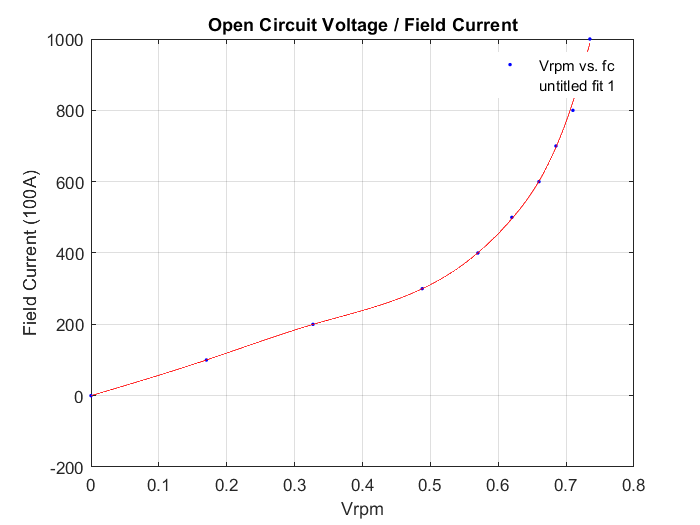

fc(1)=0;
Vrpm(1)=0; fc(2)=100;
Vrpm(2)=0.17;fc(3)=200;
Vrpm(3)=0.327;fc(4)=300;
Vrpm(4)=0.488;fc(5)=400;
Vrpm(5)=0.57;fc(6)=500;
Vrpm(6)=0.62;fc(7)=600;
Vrpm(7)=0.66;fc(8)=700;
Vrpm(8)=0.685;fc(9)=800;
Vrpm(9)=0.71;fc(10)=900;
Vrpm(10)=0.721;fc(11)=1000;
Vrpm(11)=0.735;
[xData, yData] = prepareCurveData( Vrpm, fc );

% Set up fittype and options.
ft = fittype( 'smoothingspline' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, 'Normalize', 'on' );

% plot fit with data.
% figure( 'Name', 'untitled fit 1' );
% h = plot( fitresult, xData, yData );
% title('Open Circuit Voltage / Field Current')
% legend( h, 'Vrpm vs. fc', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% 
% ylabel( 'Field Current (100A)', 'Interpreter', 'none' );
% xlabel( 'Vrpm', 'Interpreter', 'none' );
% grid on